*Copyright 2025 The MathWorks, Inc.*

# **EXERCISE 3 : Plug a custom downlink channel into the simulated 5G network   **

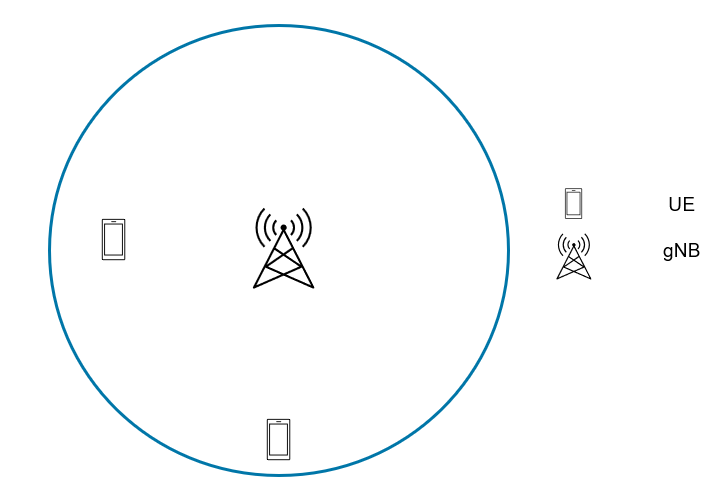

This exercise demonstrates the workflow to plug a custom channel into simulated 5G network. The goals are:

- Create a custom channel 

- Plug custom channel into the simulated network   

- Impair signal using the custom channel  

#### Close any previously opened figures and add the path to the helpers and utilities directories 

- Close all previous windows

- Add path to helpers and utilities

- Reset the random number generator for reproducibility

all_figs = findall(0, 'type', 'figure');close(all_figs); 
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); 
rng("default")  

#### Initialize Variables and Wireless Network Simulator

- Set Radius of each cell (in meters)

- Initialize the Wireless Network Simulator

- Number of frames to simulate and simulation time in seconds 

- Launch the wireless network viewer to visualize the network during simulation

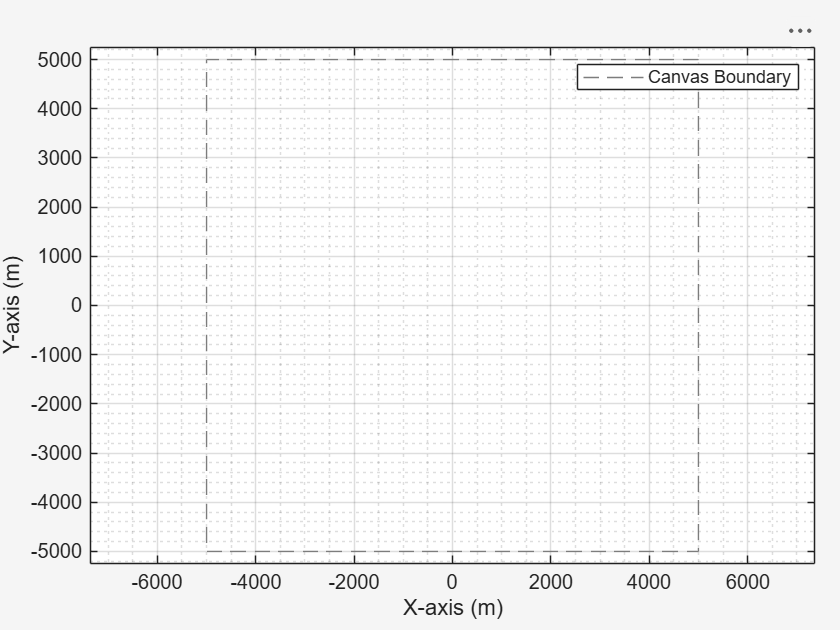

numFrameSimulation = 25;
simulationTime = numFrameSimulation*1e-2;
networkSimulator = wirelessNetworkSimulator.init;
cellRadius = 5000; 
viewerObj = wirelessNetworkViewer(CanvasSize=[10000 10000]);

#### Create a 5G NR base station 

gNBPosition = [0 0 10];
gnb = nrGNB(Position=gNBPosition, ...
    ChannelBandwidth=20e6, ...
    DuplexMode="FDD", ...
    SubcarrierSpacing=30e3, ...
    PHYAbstractionMethod="none");

Visualize the 5G base stations in the Network Viewer and add it as nodes to the network simulator

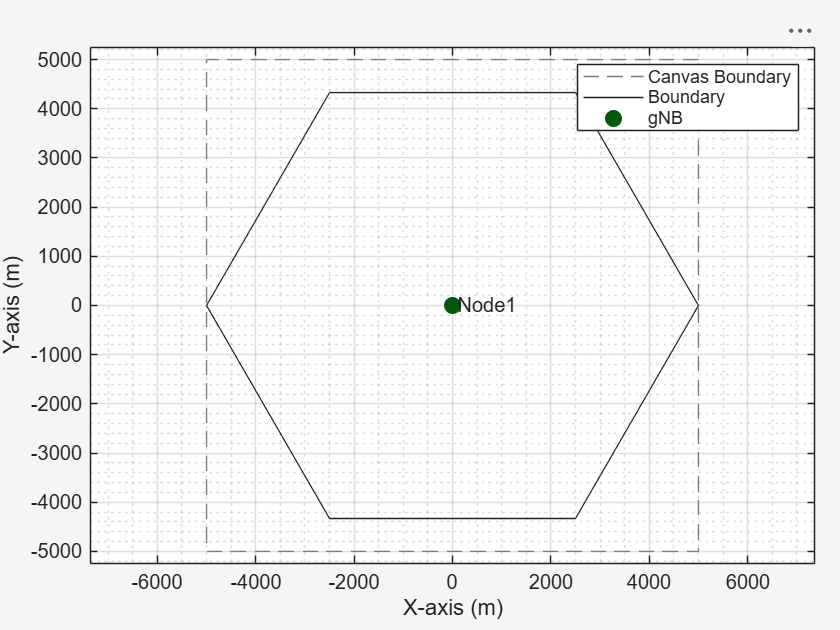

addNodes(networkSimulator,gnb);
addNodes(viewerObj,gnb,Type="gNB");
showBoundary(viewerObj,Position=gNBPosition, BoundaryShape="Hexagon",Bounds=cellRadius, Name="Cell-1")

#### Create two UE nodes, specifying their positions in Cartesian coordinates

% Create a UE (User Equipment) node
numUEs = 2;
ueNames =["UE-1";"UE-2"];       % UE Name 
uePositions = [500 500 0; 4500 100 0]; % UE position
ue = nrUE(Position=uePositions, ...
    PHYAbstractionMethod="none", ...
    Name=ueNames,NumReceiveAntennas=1, ...
    NumTransmitAntennas=1);

Visualize the 5G user equipment in the Network Viewer and add them as nodes to the network simulator

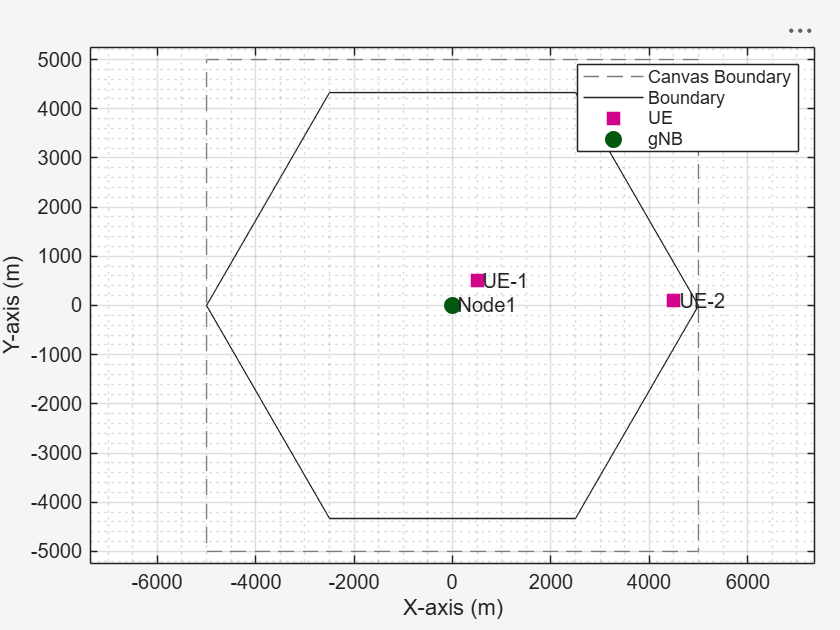

addNodes(networkSimulator,ue);
addNodes(viewerObj,ue,Type="UE");

Connect the UE nodes to the gNB node and enable full-buffer traffic

connectUE(gnb,ue,FullBufferTraffic="on");

#### Enable visualizations

The displayed visualizations and metrics correspond to the selected cell of interest.

- Cell Performance Metrics – Shows key KPIs like throughput, fairness, and buffer status 

- RLC Metrics – Displays data transmitted at the RLC layer for each UE 

- BLER Metrics – Visualizes block error rates in uplink and downlink 

- Resource Grid Allocation – Shows time-frequency resource allocation and HARQ activity 

- Channel Quality – Displays MCS variations across time and frequency 

- Simulation Summary – Compares achieved performance with theoretical limits

simSchedulingLogger = helperNRSchedulingLogger(numFrameSimulation, gnb,ue,LinkDirection="Both");

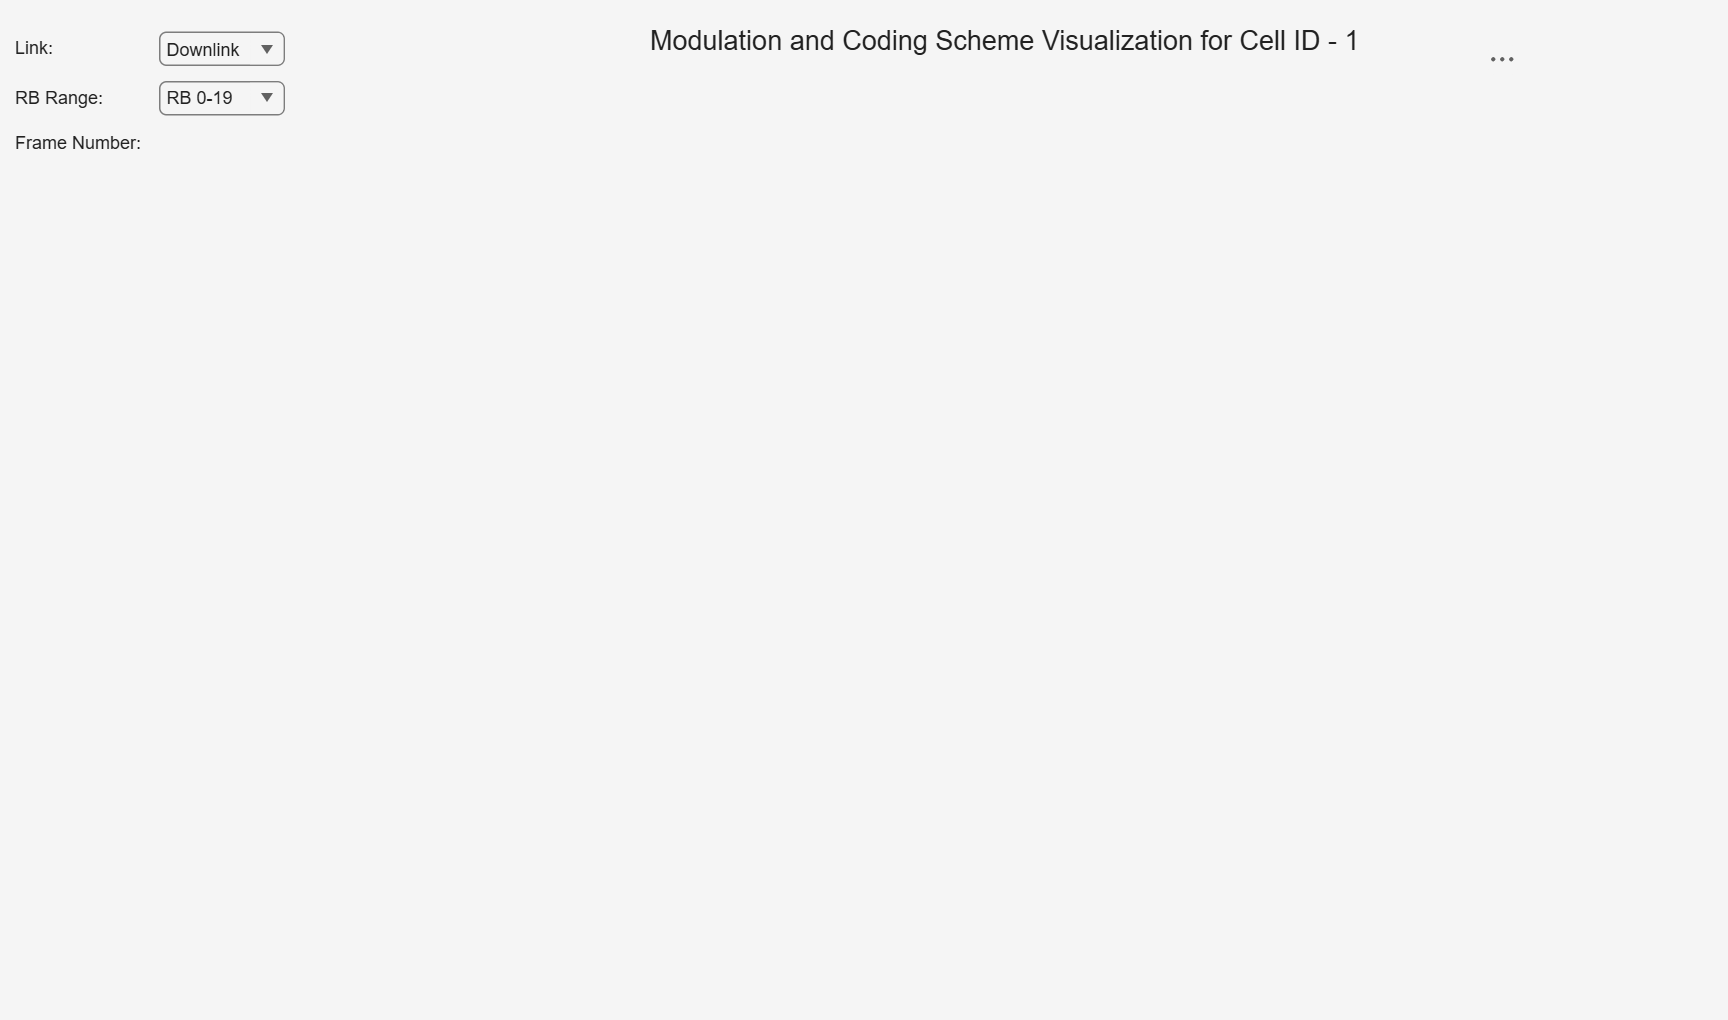

gridVisualizer = helperNRGridVisualizer(numFrameSimulation,gnb,ue, ResourceGridVisualization=false,SchedulingLogger= simSchedulingLogger,MCSGridVisualization=true);

metricsVisualizer = helperNRMetricsVisualizer(gnb,ue,RefreshRate=100,PlotSchedulerMetrics=true,PlotPhyMetrics=true,LinkDirection="Both");

# Task #1/3 Add Custom Channel Model to Network Simulator

**Instructions to complete the task**

Add a custom channel model to the network simulator.

Use the `addChannelModel()` function to add the channel model to the simulation.

Hint: Type `doc addChannelModel` in the MATLAB Command Window and refer to the *Syntax* section.

Pass the following arguments:

- `networkSimulator`

- `@myCustomChannel`

**Note: You will implement your channel model in the **`myCustomChannel`** function in Task 3.**

% <enter code below>
addChannelModel(networkSimulator,@myCustomChannel);

# Task 2/3: Run the simulation

Runs the discrete-event simulator in MATLAB to execute the network model.

**Instructions to complete the task**

Use addNodes() function to add Bluetooth LE nodes to the network simulator   

Type `doc wirelessnetworksimulator.run` in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- networkSimulator

- simulationTime

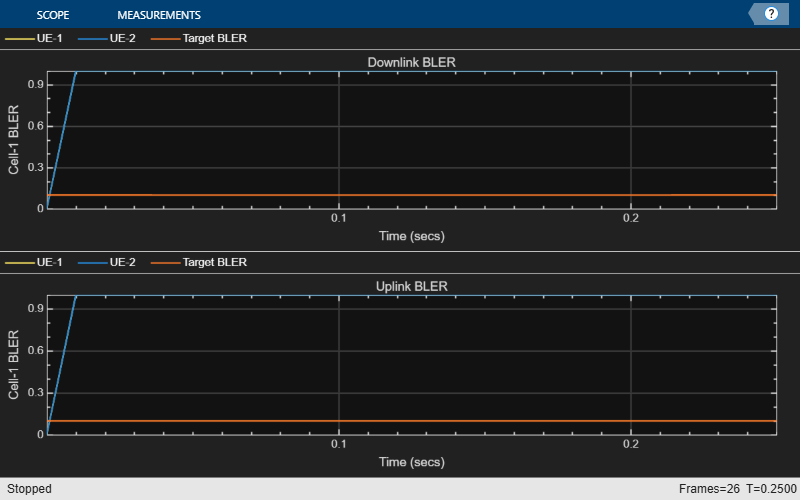

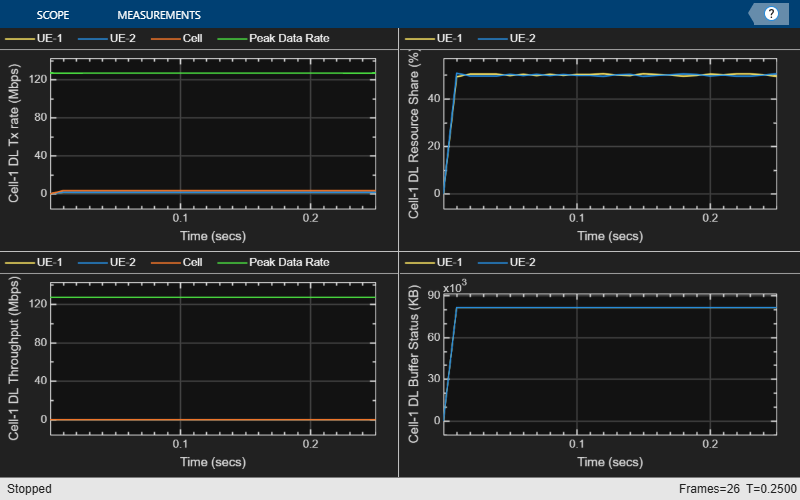

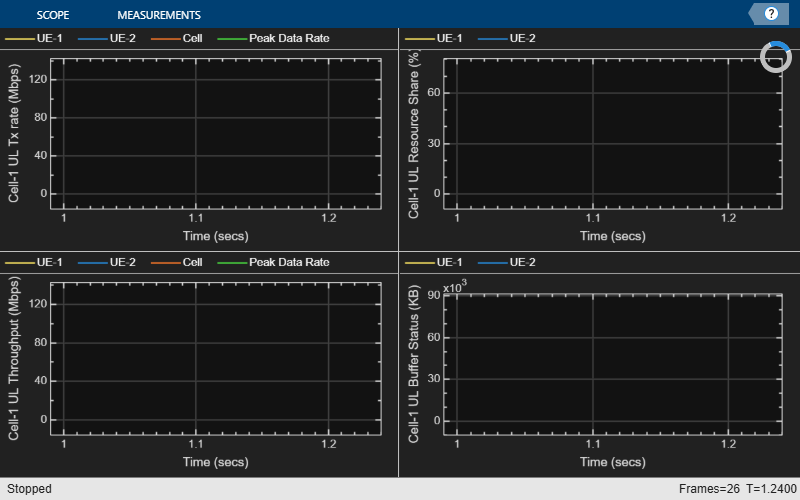

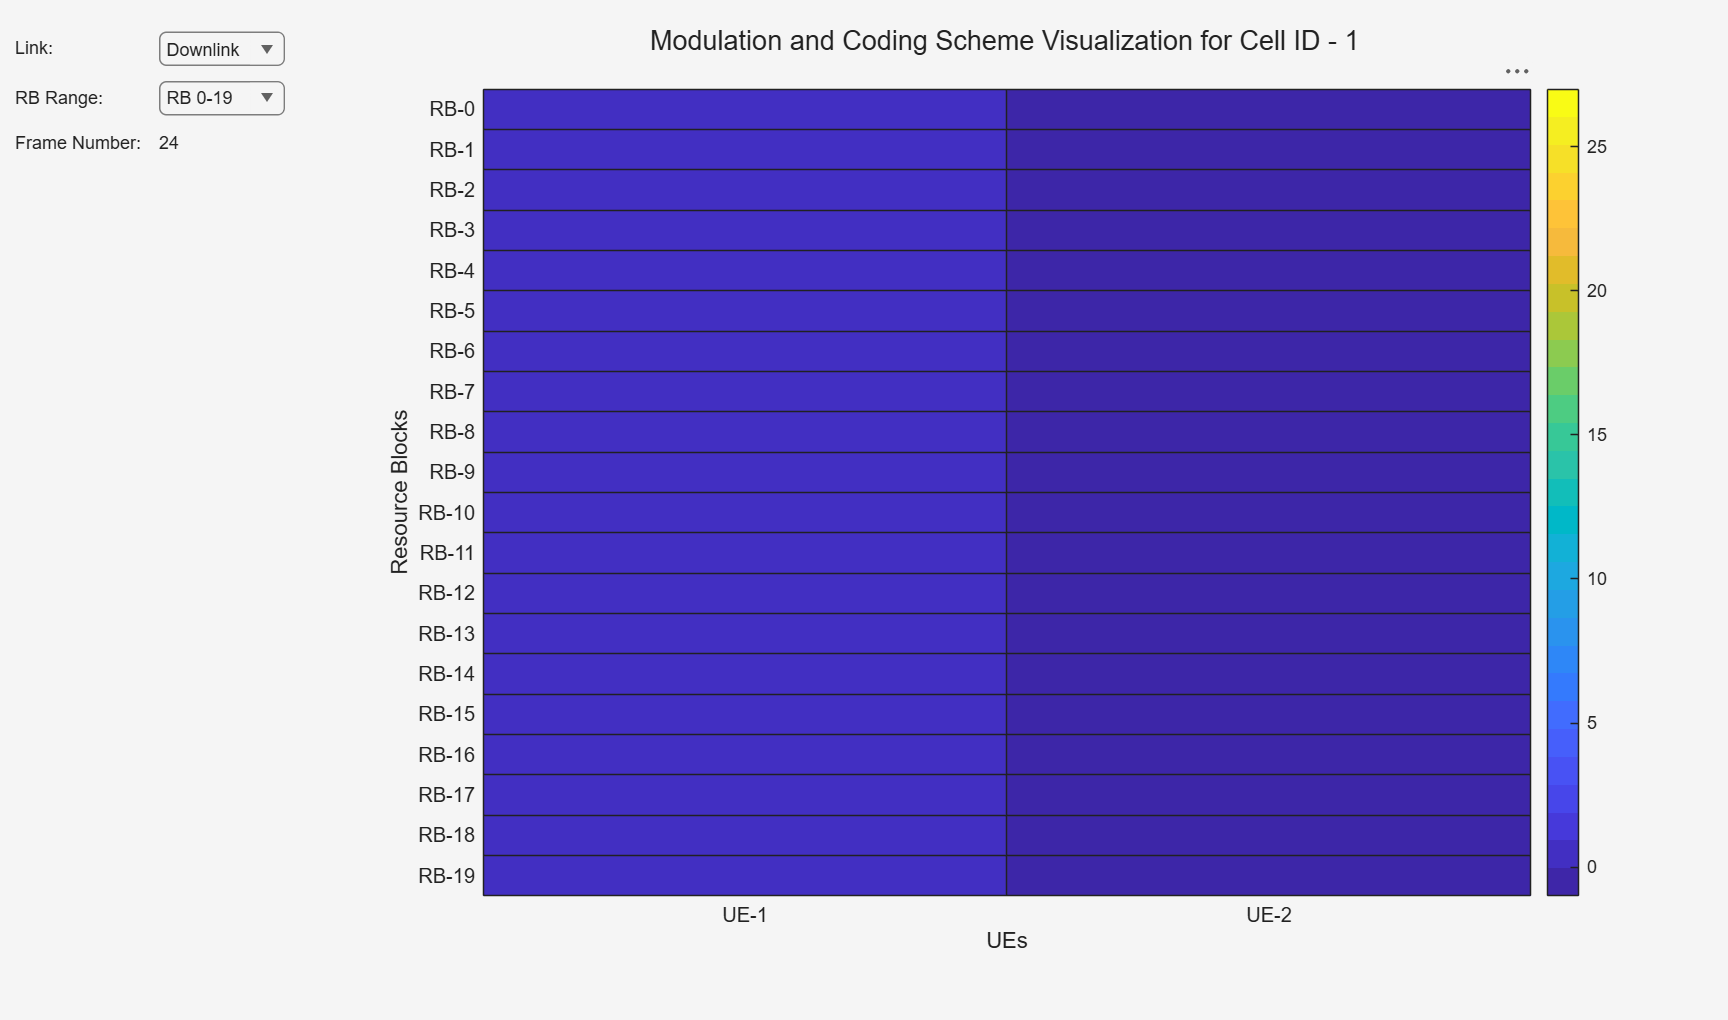

% <enter code below>
run (networkSimulator,simulationTime);

# Task #3/3 Implement custom path loss for the channel 

**Note: Before starting Task 3, place a breakpoint inside the **`myCustomChannel`** function at line **`outputData = txData;`** and run the simulation**

#### **Description of the Task** 

Follow these steps to create a custom channel model:

- The simulator passes information about the receiver and transmitter nodes as inputs to the custom function. 

- Apply free-space path loss between the base station and UE nodes. 

- Apply the custom channel model to the transmitted packets. 

`myCustomChannel` is a user-defined callback function invoked by the simulation engine whenever a packet is exchanged between any two nodes in the simulated network.

**Inputs to the function:**

- **rxInfo** (receiver information) includes: 

- ID 

- Position 

- Velocity 

- Additional receiver-related parameters 

- **txData** (transmitter data) includes: 

- Transmitter ID 

- Transmitter position 

- Transmitter velocity 

- Transmit power 

- Center frequency 

- Bandwidth 

- Sample rate 

- Antenna configuration 

- Transmitted data and other relevant parameters

**Instructions to complete the task**

Large-Scale Fading: pathLoss = 10*log10(((4*pi*distance)/(lambda))^2);

**Step 1: Calculate the wavelength of operation**

**You need to type:**

`lambda = c/txData.CenterFrequency;`

**Step-2 Calculate the distance between receiver and transmitter **

Use the `norm()` function to compute the distance between the UE and gNB.

distance = norm(p1 − p2), where p1 = (x1, y1, z1) and p2 = (x2, y2, z2).

This calculates √((x1 − x2)² + (y1 − y2)² + (z1 − z2)²).

**You need to type: **

`distance = norm(txData.TransmitterPosition - rxInfo.Position);`

**Step-3 Calculate the pathloss **

**You need to type: **

`pathLoss = 10*log10(((4*pi*distance)/(lambda))^2);`

**Step-4 Convert pathloss to linear scale  **

**You need to type: **

`scale = db2mag(-pathLoss);`

function outputData = myCustomChannel(rxInfo,txData)

Peak UL throughput: 126.91 Mbps
Achieved cell UL throughput: 0.00 Mbps
Achieved UL throughput for each UE: [0  0]
Peak UL spectral efficiency: 6.35 bits/s/Hz
Achieved UL spectral efficiency for cell: 0.00 bits/s/Hz 
Block error rate for each UE in the UL direction: [1  1]

Peak DL throughput: 126.91 Mbps
Achieved cell DL throughput: 0.00 Mbps
Achieved DL throughput for each UE: [0  0]
Peak DL spectral efficiency: 6.35 bits/s/Hz
Achieved DL spectral efficiency for cell: 0.00 bits/s/Hz
Block error rate for each UE in the DL direction: [1  1]



outputData = txData;
c = physconst('LightSpeed');
% Step-1
lambda = c/txData.CenterFrequency;
% Step-2
distance = norm(txData.TransmitterPosition - rxInfo.Position);
% Step-3
pathLoss = 10*log10(((4*pi*distance)/(lambda))^3);
outputData.Power = outputData.Power - pathLoss;
% Step-4
scale = db2mag(-pathLoss);
outputData.Data = outputData.Data*scale;

% Set Metadata
outputData.Metadata.Channel.PathGains   = 1;
outputData.Metadata.Channel.PathDelays  = 0;
outputData.Metadata.Channel.PathFilters = 1;
outputData.Metadata.Channel.SampleTimes = 0;
end

#### Display Performance Indicators

displayPerformanceIndicators(metricsVisualizer)

*Copyright 2025 The MathWorks, Inc.*